## Question A

Write a function with the definition:

    function y=act(z),

that calculate the Sigmoid function, act(x). Test the function by making a plot like the figure above

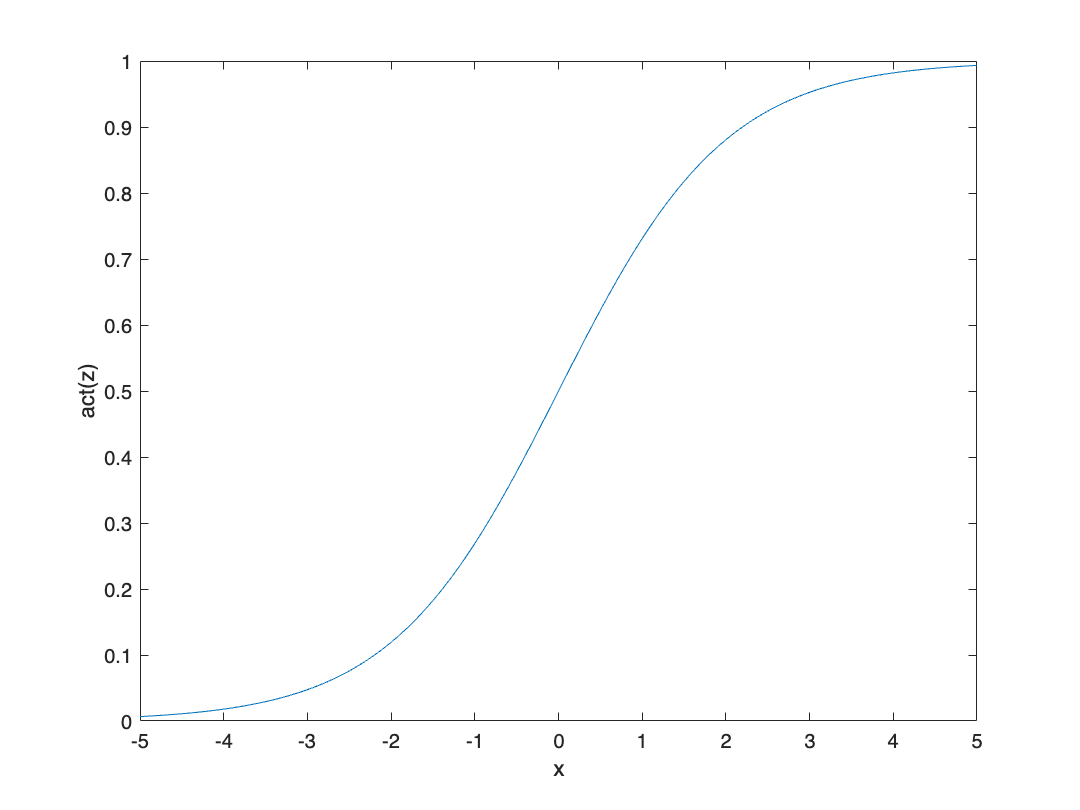

%the defined sigmoid expects the z-values as a vector
z = -5:0.1:5; 

%call activation function to find corresponding y-values
y = act(z);

%make plot
figure;
plot(z, y);
xlabel("x");
ylabel("act(z)");
xticklabels(-5:1:5)
yticklabels(0:0.1:1)

## Question B

Write a function with the definition:

    function zi=neuron_hidden(x1,x2,v1,v2,bi),

that calculate z_i(x_1, x_2, v_1, v_2, bi). Test the function by calculating 2-3 examples by hand and demonstrate that your function is valid. We will not be using neuron_hidden any further.

%define 1st set of test values
x_1 = 2;
x_2 = 0.5;
v_1 = 0.25;
v_2 = 1;
b_i = -0.5;

%run 1st test
neuron_hidden(x_1, x_2, v_1, v_2, b_i);

The calculated value is 0.6225 


%this correspponds to the hand-calculated value


%define 2nd set of test values
x_1 = -2;
x_2 = 0.5;
v_1 = 2.5;
v_2 = 10;
b_i = 0;

%run 2nd test
neuron_hidden(x_1, x_2, v_1, v_2, b_i);

The calculated value is 0.5000 


%this corresponds to the hand-calculated value

## Question C

Write a function with the definition:

    function fi=neuron(x,v,b),

where x and v are vectors with each n elements and b is a scalar. The function should calculate phi_neuron(x,v,b) and return the activation value. Test the function using the same values as in question B and in addition at least one example where n>2.

%define 1st set of test variables
x = [2, 0.5];
v = [0.25, 1];
b = -0.5;

%run 1st test
f_i = neuron(x, v, b);
fprintf("The activation value is %.4f \n", f_i)

The activation value is 0.6225 


%this corresponds to the result from question B

%define 2nd set of test variables
x = [0.5, 2, 5];
v = [2, 0.5, 0.2];
b = -3;

%run 2nd test
f_i = neuron(x, v, b);
fprintf("The activation value is %.4f \n", f_i)

The activation value is 0.5000 


%this corresponds to the hand-calculated value

## Question D

Write a function with the definition:

    function f=neural_network(x,v,b,w,c),

that calculate the output for the entire network, and using the function, neuron from question C. 

Note that x is an input vector with 2 elements, and v is a matrix [n,2] with weights for the hidden layer, so that (v_i)^1 is the first column, and (v_i)^2 in second column. Biases are in a vector, b, with n values, and c is a scalar with the bias of the output neuron. Weights are in w, which is a vector with n elements, and n can be calculated as length(b). Validate the parameters and test the function using the previous used test values.

%define test values
x = [2, 0.5];
v = [0.25, 1; 0.25, 1];
b = [-3, -3];
w = [0.2, -0.8];
c = 0.3;

%the function is called and an output value is calculated
f = neural_network(x, v, b, w, c);
fprintf("The output neuron has a value of %.3f", f)

The output neuron has a value of 0.557

## Question E

Create three functions

    function [v, b, w] = loadNetwork(fileName)

    function saveNetwork(v,b,w,fileName)

    function validateNetwork(v,b,w) 

hese functions should load/save the network data from/to data.csv, and validateNetwork should calculate and validate the row/column sums. Validate the functions using the following sums: cs=[-30.1, -39.8, -55.1, 35.0, 109.0, -29.6, -17.7, -31.7, 62.5, -43.7, 90.7, -23.5, - 41.2, -97.3 -38.7 -93.7, -14.1, -29.8, 51.7, -6.5];

%define the example neural network from the assignment
v = [8.2, -12.3; 12.2, -7.8; -9.0, 2.9; -16.9, -4.3; 24.2, -16.4; 
     6.4, 18.9; 9.6, 4.1; 0.1, -8.4; 7.4, 11.8; -7.6, 19.3; 
     12.8, 16.7; 1.6, -6.9; 23.2, 17.2; 12.1, -18.4; 
     -10.1, 3.9; -23.8, -1.6; 0.2, 13.4; 8.8, 2.8; 
     9.6, 13.3; 0.1, -30.0];

b = [-6.8; -20.8; 7.5; 25.0; 43.5; -30.2; -5.5; 7.3; 19.5; 
    -31.4; 29.3; -1.5; -42.9; -31.3; -5.6; -35.3; 
     10.7; 7.0; 7.0; 9.1];

w = [-19.2; -23.4; -56.5; 31.2; 57.7; -24.7; -25.9; 
     -30.7; 23.8; -24.0; 31.9; -16.7; -38.7; -59.7; 
     -26.9; -33.0; -38.4; -48.4; 21.8; 14.3]; 

c = 13.4;

%apply the saveNetwork function to save the data in a seperate file
saveNetwork(v, b, w, "data.csv")

%load the data from the previousle saved file (note: it would be quicker
%and more elegant just to use the matrices v, b and w defined above but the
%following was made to use the loadNetwork function we had to define)
[v_loaded, b_loaded, w_loaded] = loadNetwork("data.csv");

%apply the validateNetwork function to calculate a checksum
validateNetwork(v_loaded, b_loaded, w_loaded)

The check sum is
  -30.1000
  -39.8000
  -55.1000
   35.0000
  109.0000
  -29.6000
  -17.7000
  -31.7000
   62.5000
  -43.7000
   90.7000
  -23.5000
  -41.2000
  -97.3000
  -38.7000
  -93.7000
  -14.1000
  -29.8000
   51.7000
   -6.5000



%note: the checksum is equal to the expected one from the assignment

## Question F

Make a plot of f(x1, x2, v, b, w, c) for -2<=x1<=2 and -2<=x2<=2 and v,b,w,c as above using the ”surf” command followed by ”view(2); colorbar;”.

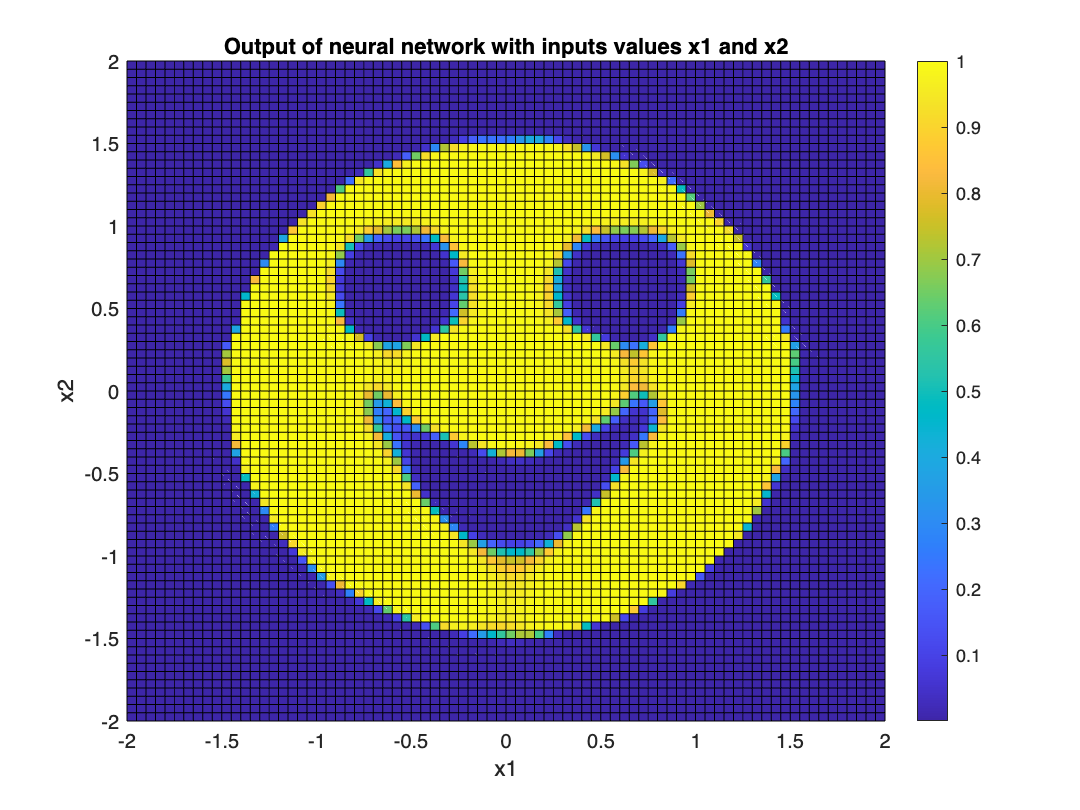

%define intervals of values for input-neurons
x1_interval = -2:0.05:2;
x2_interval = -2:0.05:2;

%create a grid of X1 and X2 values to be able to use surf()
[X1, X2] = meshgrid(x1_interval, x2_interval);

%initialize output matrix
f = zeros(size(X1));

%apply the neural_network function for all combinations of X1 and X2
for i = 1:numel(X1)
    f(i) = neural_network([X1(i), X2(i)], v, b, w, c);
end

%plot the output of the neural network
figure;
surf(X1, X2, f);
view(2); %2D-view
colorbar; %displays a colorbar so the value of each cell can be quickly gauged
title('Output of neural network with inputs values x1 and x2');
xlabel('x1');
ylabel('x2');

## Definitions

%define the Sigmoid function element-wise
function y = act(z)
    y = 1 ./ (1 + exp(-z));
end

%define the function for calculating the value of one of the hidden neurons
function z_i = neuron_hidden(x_1, x_2, v_1, v_2, b_i)
    %define the argument to the activation function
    z = v_1 * x_1 + v_2 * x_2 + b_i;

    %apply the activation function
    z_i = act(z);

    %print calculated value to screen
    fprintf("The calculated value is %.4f \n", z_i)
end

%define the neuron function
function f_i = neuron(x, v, b)
    %define the argument to the activation function
    f = dot(x, v) + b;

    %apply the activation function
    f_i = act(f);
end

%define the function for calculating the output of the entire NN
function f = neural_network(x, v, b, w, c)
    %calculate number of hidden neurons
    n = length(b);

    %initialize array to store outputs from hidden layer
    z = zeros(1,n);

    %apply neuron function on all hidden neurons
    for i = 1:n
        z(i) = neuron(x, v(i,:), b(i)); %v(i,:) tells MatLab to extract all rows in the i'th column 
    end

    %calculate the value of the output neuron
    f = neuron(z, w, c);
end

%define function for reading .csv file
function [v, b, w] = loadNetwork(fileName)
    %read the contents of the .csv file and save it as a matrix
    A = readmatrix(fileName);

    %Extract the contents of the matrix and assign them to variables
    v = A(:, 1:2);
    b = A(:, 3);
    w = A(:, 4);
end

%define function for writing .csv file
function saveNetwork(v, b, w, fileName)
    %collect the variables into a single matrix
    A = [v, b, w];

    %write the matrix to a .csv file
    writematrix(A, fileName);
end

%defines validation funtion to calculate checksum
function validateNetwork(v, b, w)
    %collect the variables into a single matrix
    A = [v, b, w];

    %calculate checksums of each row
    cs = sum(A, 2);

    %print the computed checksums to the screen
    disp("The check sum is")
    disp(cs)
end



function validateNetwork(v, b, w)
    %collect the variables into a single matrix
    A = [v, b', w'];
    
    %calculate checksums of each row
    cs = sum(A, 2);
    
    %define the expected checksums (from the assignment)
    expected_cs = [-30.1, -39.8, -55.1, 35.0, 109.0, -29.6, -17.7, -31.7, ...
                   62.5, -43.7, 90.7, -23.5, -41.2, -97.3, -38.7, -93.7, ...
                   -14.1, -29.8, 51.7, -6.5]';
    
    %use assert to verify that the calculated checksums match the expected ones
    assert(isequal(round(cs, 4), round(expected_cs, 4)), ...
           "Checksum validation failed. Computed values do not match the expected ones.");
    
    %if all checks pass, print the checksums
    disp("Checksum validation passed!");
    disp("The check sum is:");
    disp(cs);
end
